% clear; clc;

%% 1. Paramètres et chemins
path_tif = "E:\Data\Aurelie\data\chroms\119\exvivo.tif";
% path_csv = "E:\Data\Aurelie\data\chroms\119\220919\registration\centroid_gcamp_affine.csv";
path_csv = "E:\Data\Aurelie\data\chroms\119\220919\registration\biapy_centroids_matched.csv";

radius = 2;   % Demi-fenêtre en X,Y (patch 5x5)
radius_z = 1; % Demi-fenêtre en Z (volume Z-1, Z, Z+1)

% L'ordre de ton TIF (Très important pour le chargement)
ordre_tif = 'ChannelsFirst'; % Ou 'ZFirst' selon ImageJ
num_channels = 4; % Rouge,Vert,Bleu, Calcium

%% 2. Lecture du CSV
coords = readtable(path_csv);
coords = coords(2:end,:);
Z_pts = round(coords{:, 1}); % Prend toutes les lignes de la 1ère colonne
X_pts = round(coords{:, 3}); % Prend toutes les lignes de la 2ème colonne
Y_pts = round(coords{:, 2}); % Prend toutes les lignes de la 3ème colonne



NCell = height(coords);

fprintf('Préparation pour %d cellules...\n', NCell);

%% 3. CHARGEMENT COMPLET DU VOLUME 3D EN RAM
fprintf('Chargement du TIF 3D en mémoire (cela peut prendre quelques secondes)...\n');
info = imfinfo(path_tif);
total_pages = numel(info);
num_Z = total_pages / num_channels;

z_min_utile = max(1, min(Z_pts) - radius_z); % Ex: 36 - 1 = 35
z_max_utile = max(Z_pts) + radius_z;         % Ex: 81 + 1 = 82
nb_z_utiles = z_max_utile - z_min_utile + 1;

fprintf('Préparation : %d cellules. Plage Z utile : %d à %d (%d plans).\n', ...
    NCell, z_min_utile, z_max_utile, nb_z_utiles);

info = imfinfo(path_tif);
imgW = info(1).Width;
imgH = info(1).Height;

Volume_Utile = zeros(imgH, imgW, nb_z_utiles, num_channels, 'double');

hWait = waitbar(0, 'Chargement des images TIF en cours...', 'Name', 'Lecture 3D');

% Calcul du nombre total d'itérations pour la barre de progression
total_iterations = nb_z_utiles * num_channels;
compteur = 0;

% On boucle uniquement sur les plans Z dont on a besoin
for z = z_min_utile : z_max_utile
    
    % Pour ce plan Z, on charge les 4 couleurs
    for c = 1:num_channels
        
        % Formule pour trouver la page dans le gros TIF
        if strcmp(ordre_tif, 'ChannelsFirst')
            page = (z - 1) * num_channels + c;
        else
            total_Z_tif = numel(info) / num_channels;
            page = (c - 1) * total_Z_tif + z;
        end
        
        % On calcule l'indice de stockage dans notre "petit" Volume_Utile
        % Ex: Si z_min_utile = 35, le plan Z=35 ira dans la case z_idx = 1
        z_idx = z - z_min_utile + 1; 
        
        Volume_Utile(:, :, z_idx, c) = double(imread(path_tif, 'Index', page));
               % --- MISE À JOUR DE LA BARRE DE PROGRESSION ---
        compteur = compteur + 1;
        % On calcule le pourcentage (entre 0 et 1)
        progression = compteur / total_iterations;
        
        % On met à jour la barre et le texte (tous les 4 plans Z pour ne pas ralentir le code)
        if mod(compteur, 4) == 0 || compteur == total_iterations
            waitbar(progression, hWait, sprintf('Chargement : %d %% (%d / %d images)', ...
                round(progression * 100), compteur, total_iterations));
        end
    end
end
fprintf('Bloc chargé ! Dimensions : %d x %d x %d x %d\n', imgH, imgW, nb_z_utiles, num_channels);

%% 4. EXTRACTION DES INTENSITÉS
intensity_features = zeros(NCell, num_channels);

for n = 1:NCell
    cx = X_pts(n);
    cy = Y_pts(n);
    cz = Z_pts(n);
    
    % Bords X,Y
    col_min = max(1, cx - radius);
    col_max = min(imgW, cx + radius);
    row_min = max(1, cy - radius);
    row_max = min(imgH, cy + radius);
    
    % --- ADAPTATION DES BORD Z ---
    % cz est la coordonnée ABSOLUE (ex: 36).
    % Il faut la convertir en coordonnée RELATIVE à notre Volume_Utile (ex: 2)
    cz_relatif = cz - z_min_utile + 1;
    
    z_min_rel = max(1, cz_relatif - radius_z);
    z_max_rel = min(nb_z_utiles, cz_relatif + radius_z);
    
    % Extraction et moyenne
    for c = 1:num_channels
        patch_3D = Volume_Utile(row_min:row_max, col_min:col_max, z_min_rel:z_max_rel, c);
        intensity_features(n, c) = mean(patch_3D(:));
    end
end

fprintf('Extraction terminée !\n');

%% 5. Normalisation
X_base = intensity_features;
X_norm = normalize(X_base, 'range');

R = X_norm(:, 1);
G = X_norm(:, 2);
B = X_norm(:, 3);
Cal = X_norm(:, 4);

%% 3.5 VISUALISATION INTERACTIVE DU VOLUME ET DES CELLULES
% Ce bloc ouvre une fenêtre pour vérifier que le CSV est bien aligné avec le TIF

% Choix du canal à afficher (Ex: 3 pour le Vert, 4 pour le Calcium)
canal_affichage = 3; 

% On crée une nouvelle figure pour notre interface
fig_verif = figure('Name', 'Vérification de l''alignement TIF / CSV', ...
                   'NumberTitle', 'off', 'Position', [100, 100, 800, 800]);

% Création des axes pour l'image
ax = axes('Parent', fig_verif, 'Position', [0.1, 0.2, 0.8, 0.7]);

% --- ÉLÉMENTS DE CONTRÔLE (Slider et Checkbox) ---
% 1. Le slider pour changer le plan Z
slider_z = uicontrol('Parent', fig_verif, 'Style', 'slider', ...
                     'Position', [100, 50, 600, 20], ...
                     'Min', 1, 'Max', nb_z_utiles, ...
                     'Value', round(nb_z_utiles/2), ... % On commence au milieu
                     'SliderStep', [1/max(1, nb_z_utiles-1), 10/max(1, nb_z_utiles-1)]);

% 2. Le texte qui indique le Z actuel
txt_z = uicontrol('Parent', fig_verif, 'Style', 'text', ...
                  'Position', [350, 20, 100, 20], ...
                  'String', sprintf('Plan Z : %d', z_min_utile + round(nb_z_utiles/2) - 1));

% 3. La case à cocher pour afficher les cellules
check_cellules = uicontrol('Parent', fig_verif, 'Style', 'checkbox', ...
                           'Position', [100, 80, 200, 20], ...
                           'String', 'Afficher les cellules (CSV)', ...
                           'Value', 1); % Cochée par défaut

% Stockage des données dans la figure pour y accéder depuis la fonction callback
guidata(fig_verif, struct('Volume', Volume_Utile, 'X', X_pts, 'Y', Y_pts, ...
                          'Z', Z_pts, 'Zmin', z_min_utile, 'Ax', ax, ...
                          'Txt', txt_z, 'Check', check_cellules, 'Canal', canal_affichage, 'Radius', radius));

% Définition de la fonction qui s'exécute quand on touche au slider ou à la checkbox
set(slider_z, 'Callback', @update_image);
set(check_cellules, 'Callback', @update_image);

% Affichage initial
update_image(slider_z, []);

disp('Mettez en pause le script ou fermez la figure pour continuer l''extraction...');
%uiwait(fig_verif); % Le code s'arrête ici tant que tu n'as pas fermé la fenêtre !


%% --- FONCTION DE MISE À JOUR DE L'IMAGE (À copier TOUT À LA FIN de ton script) ---
%% --- FONCTION DE MISE À JOUR DE L'IMAGE EN COULEUR ---
function update_image(hObject, ~)
    % Récupération des données stockées dans la figure
    data = guidata(hObject);
    
    % Récupération du Z actuel
    z_relatif = round(get(findobj(hObject.Parent, 'Style', 'slider'), 'Value'));
    z_absolu = data.Zmin + z_relatif - 1;
    
    % Mise à jour du texte
    set(data.Txt, 'String', sprintf('Plan Z : %d', z_absolu));
    
    % --- CRÉATION DE L'IMAGE COMPOSITE RGB ---
    % On extrait les 3 canaux correspondant aux couleurs (Bleu=1, Rouge=2, Vert=3)
    % Ajuste les indices si l'ordre de ton microscope est différent !
    img_Bleu  = data.Volume(:, :, z_relatif, 1); 
    img_Rouge = data.Volume(:, :, z_relatif, 2);
    img_Vert  = data.Volume(:, :, z_relatif, 3);
    
    % Normalisation de chaque canal entre 0 et 1 pour l'affichage
    % On utilise imadjust ou simplement une division par le max local
    max_B = max(img_Bleu(:));  if max_B == 0, max_B = 1; end
    max_R = max(img_Rouge(:)); if max_R == 0, max_R = 1; end
    max_V = max(img_Vert(:));  if max_V == 0, max_V = 1; end
    
    % On booste un peu le contraste (multiplier par 1.5) pour bien voir les fluos
    canal_R = min(1, (img_Rouge / max_R) * 1.5);
    canal_V = min(1, (img_Vert / max_V) * 1.5);
    canal_B = min(1, (img_Bleu / max_B) * 1.5);
    
    % On assemble les 3 matrices en un cube (H x W x 3) que MATLAB comprend comme une image RGB
    img_RGB = cat(3, canal_R, canal_V, canal_B);
    
    % Affichage de la belle image en couleur !
    imshow(img_RGB, 'Parent', data.Ax);
    hold(data.Ax, 'on');
    
    % --- AFFICHAGE DES CELLULES ---
    if get(data.Check, 'Value') == 1
        % On cherche les cellules qui se trouvent sur ce plan Z précis
        idx_z = find(data.Z == z_absolu);
        
        if ~isempty(idx_z)
            % On trace des cercles BLANCS autour des centroïdes pour bien les voir sur les couleurs
            viscircles(data.Ax, [data.X(idx_z), data.Y(idx_z)], ...
                       repmat(data.Radius, length(idx_z), 1), ...
                       'Color', 'w', 'LineWidth', 1.0);
            
            % Écrire le numéro de la cellule (en jaune pour ressortir)
            for k = 1:length(idx_z)
                text(data.Ax, data.X(idx_z(k)) + 5, data.Y(idx_z(k)), ...
                     num2str(idx_z(k)), 'Color', 'y', 'FontSize', 8, 'FontWeight', 'bold');
            end
        end
    end
    hold(data.Ax, 'off');
end


% path_colorcell = "E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_invivo_20260424.mat";
% path_colorcell = "E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_exvivo_validatedprediction_20260424.mat";
path_colorcell ="E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_exvivo_biapy_20260424.mat";
load (path_colorcell)
Y_num = str2double(string(colorcell));


% On recrée la variable catégorielle proprement avec les 8 couleurs
classNames = {'rouge','vert','bleu','jaune','magenta','cyan','blanc','noir'};
Ycat = categorical(Y_num, 1:8, classNames);

R = X_norm(:, 1);
G = X_norm(:, 2);
B = X_norm(:, 3);
Cal = X_norm(:, 4);

% bg_B = prctile(B, 5);
% bg_R = prctile(R, 5);
% bg_G = prctile(G, 5);
% 
% B_corr = max(0, B - bg_B);
% R_corr = max(0, R - bg_R);
% G_corr = max(0, G - bg_G);
% 
% % Calcul des proportions avec les valeurs corrigées
% Somme = R_corr + G_corr + B_corr + 0.001;
% r = R_corr ./ Somme;
% g = G_corr ./ Somme;
% b = B_corr ./ Somme;

% 2. Calcul des coordonnées chromatiques (r, g, b)
% La somme r + g + b fera toujours 1
Somme = R + G + B + 0.001; % +0.001 pour éviter la division par zéro
r = R ./ Somme;
g = G ./ Somme;
b = B ./ Somme;

% 3. Projection géométrique dans un triangle équilatéral 2D
% Sommets : Vert=(0,0), Rouge=(1,0), Bleu=(0.5, sqrt(3)/2)
X_tri = r + (b * 0.5);
Y_tri = b * (sqrt(3) / 2);

% 4. Préparation des couleurs d'affichage pour les 7 classes
% L'ordre correspond à tes categories : rouge, vert, bleu, jaune, magenta, cyan, blanc
couleurs_affichage = [
    1.0  0.0  0.0;  % 1. Rouge
    0.0  0.8  0.0;  % 2. Vert
    0.0  0.0  1.0;  % 3. Bleu
    0.9  0.9  0.0;  % 4. Jaune
    1.0  0.0  1.0;  % 5. Magenta
    0.0  0.8  0.8;  % 6. Cyan
    0.6  0.6  0.6;  % 7. Blanc (gris)
    0.0  0.0  0.0   % 8. Noir (NOUVEAU)
];

% 5. Dessin de la figure
figure('Name', 'Triangle de Maxwell', 'Color', 'w');
hold on;

% Dessin des bordures du triangle
plot([0, 1, 0.5, 0], [0, 0, sqrt(3)/2, 0], 'k-', 'LineWidth', 1.5);

% --- 5c. Ajout des valeurs sur les axes (0 à 1) ---
pas = 0.25; 
for frac = pas:pas:1-pas
    % Axe Bas (Vert -> Rouge) : Proportion de Rouge
    text(frac, -0.04, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'center', 'Color', [0.6 0 0]);
    
    % Axe Droit (Rouge -> Bleu) : Proportion de Bleu
    x_droit = 1 - (frac/2);
    y_droit = frac * sqrt(3)/2;
    text(x_droit + 0.03, y_droit, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'left', 'Color', [0 0 0.6]);
    
    % Axe Gauche (Bleu -> Vert) : Proportion de Vert
    x_gauche = 0.5 - (frac/2);
    y_gauche = (1-frac) * sqrt(3)/2;
    text(x_gauche - 0.03, y_gauche, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'right', 'Color', [0 0.5 0]);
end

% Ajout du texte aux sommets
text(1.02, 0, 'Rouge', 'FontWeight', 'bold', 'HorizontalAlignment', 'left');
text(-0.02, 0, 'Vert', 'FontWeight', 'bold', 'HorizontalAlignment', 'right');
text(0.5, sqrt(3)/2 + 0.02, 'Bleu', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

% 6. Tracer les cellules (Nuage de points)
% gscatter regroupe automatiquement les points par classe (Ycat_filt)
gscatter(X_tri, Y_tri, Ycat, couleurs_affichage, '.', 15);
for k = 1:length(X_tri)
    % On décale légèrement le texte en X et en Y pour qu'il soit lisible
    text(X_tri(k) + 0.015, Y_tri(k), num2str(k), ...
         'FontSize', 7, 'Color', [0.4 0.4 0.4]); % Gris pour ne pas masquer les couleurs
end

% title('Répartition chromatique des cellules (Triangle de Maxwell)');
axis equal; % Pour que le triangle ne soit pas déformé
axis off;   % Cacher les axes X et Y classiques
legend off
hold off;

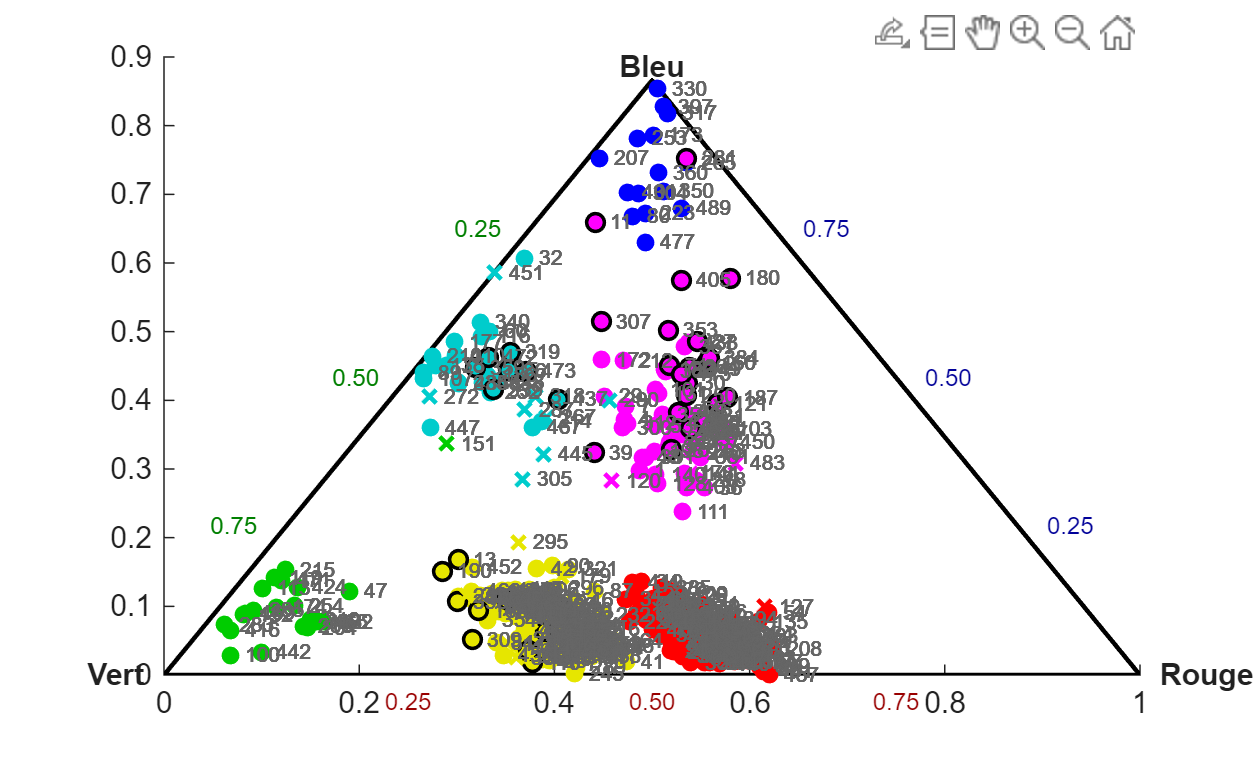

% --- 1. Chargement des données ---
path_colorcell ="E:\Data\Aurelie\data\chroms\119\220919\registration\colorcell_exvivo_biapy_20260424.mat";
load(path_colorcell)
Y_num = str2double(string(colorcell));

% Recréer la variable catégorielle proprement
classNames = {'rouge','vert','bleu','jaune','magenta','cyan','blanc','noir'};
Ycat = categorical(Y_num, 1:8, classNames);

R = X_norm(:, 1);
G = X_norm(:, 2);
B = X_norm(:, 3);

% --- 2. Calcul des coordonnées chromatiques ---
Somme = R + G + B + 0.001; 
r = R ./ Somme;
g = G ./ Somme;
b = B ./ Somme;

% --- 3. Projection géométrique (Triangle de Maxwell) ---
X_tri = r + (b * 0.5);
Y_tri = b * (sqrt(3) / 2);

% --- 4. Préparation des couleurs d'affichage ---
couleurs_affichage = [
    1.0 0.0 0.0; % 1. Rouge
    0.0 0.8 0.0; % 2. Vert
    0.0 0.0 1.0; % 3. Bleu
    0.9 0.9 0.0; % 4. Jaune
    1.0 0.0 1.0; % 5. Magenta
    0.0 0.8 0.8; % 6. Cyan
    0.6 0.6 0.6; % 7. Blanc
    0.0 0.0 0.0  % 8. Noir
];

% =========================================================================
%                 ÉTAPES 5 et 6 FUSIONNÉES (Graphique final)
% =========================================================================

figure('Name', 'Triangle de Maxwell', 'Color', 'w');
hold on;

% ---- ÉTAPE 5 : Tracer l'ossature du triangle ----
plot([0, 1, 0.5, 0], [0, 0, sqrt(3)/2, 0], 'k-', 'LineWidth', 1.5);

% Ajout des graduations sur les axes (0 à 1)
pas = 0.25;
for frac = pas:pas:1-pas
    text(frac, -0.04, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'center', 'Color', [0.6 0 0]);
    
    x_droit = 1 - (frac/2);
    y_droit = frac * sqrt(3)/2;
    text(x_droit + 0.03, y_droit, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'left', 'Color', [0 0 0.6]);
    
    x_gauche = 0.5 - (frac/2);
    y_gauche = (1-frac) * sqrt(3)/2;
    text(x_gauche - 0.03, y_gauche, sprintf('%.2f', frac), 'FontSize', 8, 'HorizontalAlignment', 'right', 'Color', [0 0.5 0]);
end

% Ajout du texte aux sommets
text(1.02, 0, 'Rouge', 'FontWeight', 'bold', 'HorizontalAlignment', 'left');
text(-0.02, 0, 'Vert', 'FontWeight', 'bold', 'HorizontalAlignment', 'right');
text(0.5, sqrt(3)/2 + 0.02, 'Bleu', 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

% --- 6. Tracer les cellules avec distinction : Croix (tout mauvais) ou Bordure noire (un seul mauvais) ---


seuil_R = 5000; % Seuil d'intensité pour R
seuil_G = 4000; % Seuil d'intensité pour G
seuil_B = 4000; % Seuil d'intensité pour B

% Extraire les intensités brutes pour simplifier l'écriture
R_brut = X_base(:,1);
G_brut = X_base(:,2);
B_brut = X_base(:,3);


categories_list = categories(Ycat);

for i = 1:length(categories_list)
    idx_cat = (Ycat == categories_list{i});
    nom_cat = string(categories_list{i});
    
    % Initialisation des masques
    idx_tout_mauvais = false(size(Ycat)); 
    idx_un_seul_mauvais = false(size(Ycat)); 
    
    switch nom_cat
        case 'rouge'
            idx_tout_mauvais = idx_cat & (R_brut < seuil_R);
            % Pas d'erreur "partielle" pour une couleur pure
            
        case 'vert'
            idx_tout_mauvais = idx_cat & (G_brut < seuil_G);
            
        case 'bleu'
            idx_tout_mauvais = idx_cat & (B_brut < seuil_B);
            
        case 'jaune' % Vert + Rouge
            % Tout est mauvais : R < seuil ET G < seuil
            idx_tout_mauvais = idx_cat & (R_brut < seuil_R) & (G_brut < seuil_G);
            % Un seul est mauvais : R < seuil OU G < seuil (excluant ceux où tout est mauvais)
            idx_un_seul_mauvais = idx_cat & ((R_brut < seuil_R) | (G_brut < seuil_G)) & ~idx_tout_mauvais;
            
        case 'magenta' % Bleu + Rouge
            idx_tout_mauvais = idx_cat & (R_brut < seuil_R) & (B_brut < seuil_B);
            idx_un_seul_mauvais = idx_cat & ((R_brut < seuil_R) | (B_brut < seuil_B)) & ~idx_tout_mauvais;
            
        case 'cyan' % Vert + Bleu
            idx_tout_mauvais = idx_cat & (G_brut < seuil_G) & (B_brut < seuil_B);
            idx_un_seul_mauvais = idx_cat & ((G_brut < seuil_G) | (B_brut < seuil_B)) & ~idx_tout_mauvais;
            
        case 'blanc' % Vert + Rouge + Bleu
            % Tout est mauvais : Les 3 sont sous le seuil
            idx_tout_mauvais = idx_cat & (R_brut < seuil_R) & (G_brut < seuil_G) & (B_brut < seuil_B);
            % Un ou deux mauvais :
            idx_un_seul_mauvais = idx_cat & ((R_brut < seuil_R) | (G_brut < seuil_G) | (B_brut < seuil_B)) & ~idx_tout_mauvais;
            
        case 'noir'
            idx_tout_mauvais = idx_cat;
    end
    
    % Les cellules parfaites
    idx_parfait = idx_cat & ~idx_tout_mauvais & ~idx_un_seul_mauvais;
    
    % 1. Parfait (Intensités OK) -> Point plein sans bordure
    if any(idx_parfait)
        scatter(X_tri(idx_parfait), Y_tri(idx_parfait), 35, couleurs_affichage(i,:), ...
            'filled', 'MarkerEdgeColor', 'none'); 
    end
    
    % 2. Une seule (ou partiellement) intensité mauvaise -> Point plein avec bordure NOIRE
    if any(idx_un_seul_mauvais)
        scatter(X_tri(idx_un_seul_mauvais), Y_tri(idx_un_seul_mauvais), 35, couleurs_affichage(i,:), ...
            'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
    end
    
    % 3. Toutes les intensités requises mauvaises -> CROIX ('x') avec la couleur correspondante
    if any(idx_tout_mauvais)
        scatter(X_tri(idx_tout_mauvais), Y_tri(idx_tout_mauvais), 40, couleurs_affichage(i,:), ...
            'x', 'LineWidth', 1.5); 
    end

    for k = 1:length(X_tri)
    % On décale légèrement le texte en X et en Y pour qu'il soit lisible
    text(X_tri(k) + 0.015, Y_tri(k), num2str(k), ...
         'FontSize', 7, 'Color', [0.4 0.4 0.4]); % Gris pour ne pas masquer les couleurs
    end
end

% --- 7. Calcul des statistiques et pourcentages d'erreurs (Version Live Editor) ---

% Initialisation des tableaux pour stocker les résultats
Couleur = strings(0);
Total = zeros(0, 1);
Parfait_Nb = zeros(0, 1);
Parfait_Pct = zeros(0, 1);
Err1_Nb = zeros(0, 1);
Err1_Pct = zeros(0, 1);
ToutFaux_Nb = zeros(0, 1);
ToutFaux_Pct = zeros(0, 1);

total_cellules = length(Ycat);

liste_cellules_tout_mauvais = [];
liste_cellules_un_mauvais = [];


for i = 1:length(categories_list)
    idx_cat = (Ycat == categories_list{i});
    nom_cat = string(categories_list{i});
    n_total_cat = sum(idx_cat);
    
    if n_total_cat == 0
        continue;
    end
    
    idx_tout_mauvais = false(size(Ycat)); 
    idx_un_seul_mauvais = false(size(Ycat)); 
    
    switch nom_cat
        case 'rouge'
            idx_tout_mauvais = idx_cat & (R_brut < seuil_R);
        case 'vert'
            idx_tout_mauvais = idx_cat & (G_brut < seuil_G);
        case 'bleu'
            idx_tout_mauvais = idx_cat & (B_brut < seuil_B);
        case 'jaune' 
            idx_tout_mauvais = idx_cat & (R_brut < seuil_R) & (G_brut < seuil_G);
            idx_un_seul_mauvais = idx_cat & ((R_brut < seuil_R) | (G_brut < seuil_G)) & ~idx_tout_mauvais;
        case 'magenta' 
            idx_tout_mauvais = idx_cat & (R_brut < seuil_R) & (B_brut < seuil_B);
            idx_un_seul_mauvais = idx_cat & ((R_brut < seuil_R) | (B_brut < seuil_B)) & ~idx_tout_mauvais;
        case 'cyan' 
            idx_tout_mauvais = idx_cat & (G_brut < seuil_G) & (B_brut < seuil_B);
            idx_un_seul_mauvais = idx_cat & ((G_brut < seuil_G) | (B_brut < seuil_B)) & ~idx_tout_mauvais;
        case 'blanc' 
            idx_tout_mauvais = idx_cat & (R_brut < seuil_R) & (G_brut < seuil_G) & (B_brut < seuil_B);
            idx_un_seul_mauvais = idx_cat & ((R_brut < seuil_R) | (G_brut < seuil_G) | (B_brut < seuil_B)) & ~idx_tout_mauvais;
        case 'noir'
            idx_tout_mauvais = idx_cat;
    end
     % --- STOCKAGE DES IDs ---
    % find(masque) renvoie les index (lignes) où le masque est Vrai.
    ids_tout_faux = find(idx_tout_mauvais);
    ids_un_faux = find(idx_un_seul_mauvais);
    
    % On les ajoute à nos listes globales (vecteurs colonnes)
    liste_cellules_tout_mauvais = [liste_cellules_tout_mauvais ; ids_tout_faux];
    liste_cellules_un_mauvais = [liste_cellules_un_mauvais ; ids_un_faux];

    % Comptage absolu
    n_tout_faux = sum(idx_tout_mauvais);
    n_1_err = sum(idx_un_seul_mauvais);
    n_parfait = n_total_cat - n_tout_faux - n_1_err;
    
    % Enregistrement dans les colonnes
    Couleur(end+1, 1) = nom_cat;
    Total(end+1, 1) = n_total_cat;
    Parfait_Nb(end+1, 1) = n_parfait;
    Parfait_Pct(end+1, 1) = round((n_parfait / n_total_cat) * 100, 1);
    Err1_Nb(end+1, 1) = n_1_err;
    Err1_Pct(end+1, 1) = round((n_1_err / n_total_cat) * 100, 1);
    ToutFaux_Nb(end+1, 1) = n_tout_faux;
    ToutFaux_Pct(end+1, 1) = round((n_tout_faux / n_total_cat) * 100, 1);
end

% Ajout de la ligne GLOBALE à la fin
Couleur(end+1, 1) = "GLOBAL";
Total(end+1, 1) = sum(Total);
Parfait_Nb(end+1, 1) = sum(Parfait_Nb);
Parfait_Pct(end+1, 1) = round((sum(Parfait_Nb) / sum(Total(1:end-1))) * 100, 1);
Err1_Nb(end+1, 1) = sum(Err1_Nb);
Err1_Pct(end+1, 1) = round((sum(Err1_Nb) / sum(Total(1:end-1))) * 100, 1);
ToutFaux_Nb(end+1, 1) = sum(ToutFaux_Nb);
ToutFaux_Pct(end+1, 1) = round((sum(ToutFaux_Nb) / sum(Total(1:end-1))) * 100, 1);

% Création et affichage de la table
Statistiques_Seuillage = table(Couleur, Total, Parfait_Nb, Parfait_Pct, Err1_Nb, Err1_Pct, ToutFaux_Nb, ToutFaux_Pct, ...
    'VariableNames', {'Couleur', 'Total_Cellules', 'Parfait_N', 'Parfait_%', 'Une_Erreur_N', 'Une_Erreur_%', 'Tout_Faux_N', 'Tout_Faux_%'});

% Affiche la table (Live Editor va créer un beau tableau graphique)
disp('Seuils utilisés : R = 5000 | G = 4500 | B = 4000')

Seuils utilisés : R = 5000 | G = 4500 | B = 4000


disp(Statistiques_Seuillage)

     Couleur     Total_Cellules    Parfait_N    Parfait_%    Une_Erreur_N    Une_Erreur_%    Tout_Faux_N    Tout_Faux_%
    _________    ______________    _________    _________    ____________    ____________    ___________    ___________

    "rouge"           164             162          98.8            0                0             2             1.2    
    "vert"             22              21          95.5            0                0             1             4.5    
    "bleu"             15              15           100            0                0             0               0    
    "jaune"           179             157          87.7           12              6.7            10             5.6    
    "ma

% On rassemble les vraies coordonnées d'origine et la couleur ground truth
Table_Cellules = table((1:length(X_tri))', X_pts, Y_pts, Z_pts, Ycat, ...
    'VariableNames', {'ID_Cellule', 'X', 'Y', 'Z', 'Couleur_CSV'});

% Ouvre le tableau dans une fenêtre interactive MATLAB (très pratique pour chercher)
% openvar('Table_Cellules');
return

figure
gscatter(X_base(:,1), X_base(:,2), Ycat, couleurs_affichage, '.', 15);
title ('red/green')
legend off
xlabel('red');
ylabel('green');

figure
gscatter(X_base(:,1), X_base(:,3), Ycat, couleurs_affichage, '.', 15);
title ('red/blue')
legend off
xlabel('red');
ylabel('blue');

figure
gscatter(X_base(:,2), X_base(:,3), Ycat, couleurs_affichage, '.', 15);
title ('green/blue')
legend off
xlabel('green');
ylabel('blue');

scatter3(X_base(:,1), X_base(:,2), X_base(:,3), 64, double(Ycat), 'filled');
colormap(couleurs_affichage);
caxis([1 8]);
xlabel('red');
ylabel('green');
zlabel('blue');


classNames = {'rouge','vert','bleu','jaune','magenta','cyan','blanc','noir'};
Ycat = categorical(Y_num, 1:8, classNames);

couleurs_affichage = [
    1.0 0.0 0.0;   % rouge
    0.0 0.8 0.0;   % vert
    0.0 0.0 1.0;   % bleu
    0.9 0.9 0.0;   % jaune
    1.0 0.0 1.0;   % magenta
    0.0 0.8 0.8;   % cyan
    0.6 0.6 0.6;   % blanc/gris
    0.0 0.0 0.0    % noir
];

figure('Color','w');
hold on;
grid on;

for k = 1:8
    idx = (Y_num == k);
    scatter3(X_base(idx,1), X_base(idx,2), X_base(idx,3), ...
        15, couleurs_affichage(k,:), 'filled');
end

title('Graphique 3D');
xlabel('green');
ylabel('blue');
zlabel('3e variable');
legend off;
axis vis3d;
view(35,25);

videoFile = fullfile('E:', 'rotation_graph_3d.mp4');
v = VideoWriter(videoFile, 'MPEG-4');
v.FrameRate = 20;
v.Quality = 100;
open(v);

for az = 1:2:360
    view(az, 25);
    drawnow;
    frame = getframe(gcf);
    writeVideo(v, frame);
end

close(v);

figure
nbbin=40;
histogram (X_base(:,1),nbbin)
box off
% Finalize
% Finalize the figure and save the histogram
title('Histogram of Red Values');
xlabel('Red Intensity');
ylabel('Frequency');
xline (4000,'Color','r') 
figure
histogram (X_base(:,2),nbbin)
box off
% Finalize
% Finalize the figure and save the histogram
title('Histogram of green Values');
xlabel('green Intensity');
ylabel('Frequency');
xline (4000,'Color','r') 

figure

histogram (X_base(:,3),nbbin)
box off
% Finalize
% Finalize the figure and save the histogram
title('Histogram of blue Values');
xlabel('blue Intensity');
ylabel('Frequency');
xline (4000,'Color','r') 

## --- 8. EXTRACTION D'UN PATCH 50x50 ET SAUVEGARDE EN MOSAÏQUE ---

%liste_cellules_tout_mauvais = [liste_cellules_tout_mauvais ; ids_tout_faux];
   % liste_cellules_un_mauvais

%cell_id_a_extraire = 451; 
for cell_id_a_extraire=liste_cellules_un_mauvais'

    
dossier_sortie = 'E:\Data\Aurelie\data\chroms\119\mosaiques_cellules1faible'; 

% Récupérer la couleur de la cellule
index_couleur = double(Ycat(cell_id_a_extraire)); % Ex: 1 pour rouge, 4 pour jaune...
rgb_cellule = couleurs_affichage(index_couleur, :);

% Appel de la fonction avec la couleur en plus
sauvegarder_mosaique_cellule(cell_id_a_extraire, Volume_Utile, X_pts, Y_pts, Z_pts, z_min_utile, rgb_cellule, dossier_sortie);
end

Mosaïque de la cellule 13 sauvegardée.


Mosaïque de la cellule 110 sauvegardée.


Mosaïque de la cellule 163 sauvegardée.


Mosaïque de la cellule 164 sauvegardée.


Mosaïque de la cellule 170 sauvegardée.


Mosaïque de la cellule 190 sauvegardée.


Mosaïque de la cellule 217 sauvegardée.


Mosaïque de la cellule 309 sauvegardée.


Mosaïque de la cellule 346 sauvegardée.


Mosaïque de la cellule 395 sauvegardée.


Mosaïque de la cellule 436 sauvegardée.


Mosaïque de la cellule 478 sauvegardée.


Mosaïque de la cellule 11 sauvegardée.


Mosaïque de la cellule 20 sauvegardée.


Mosaïque de la cellule 27 sauvegardée.


Mosaïque de la cellule 30 sauvegardée.


Mosaïque de la cellule 39 sauvegardée.


Mosaïque de la cellule 71 sauvegardée.


Mosaïque de la cellule 121 sauvegardée.


Mosaïque de la cellule 160 sauvegardée.


Mosaïque de la cellule 180 sauvegardée.


Mosaïque de la cellule 187 sauvegardée.


Mosaïque de la cellule 250 sauvegardée.


Mosaïque de la cellule 251 sauvegardée.


Mosaïque de la cellule 264 sauvegardée.


Mosaïque de la cellule 281 sauvegardée.


Mosaïque de la cellule 307 sauvegardée.


Mosaïque de la cellule 333 sauvegardée.


Mosaïque de la cellule 353 sauvegardée.


Mosaïque de la cellule 365 sauvegardée.


Mosaïque de la cellule 384 sauvegardée.


Mosaïque de la cellule 405 sauvegardée.


Mosaïque de la cellule 415 sauvegardée.


Mosaïque de la cellule 86 sauvegardée.


Mosaïque de la cellule 319 sauvegardée.


Mosaïque de la cellule 339 sauvegardée.


Mosaïque de la cellule 359 sauvegardée.


Mosaïque de la cellule 437 sauvegardée.


Mosaïque de la cellule 472 sauvegardée.


Mosaïque de la cellule 473 sauvegardée.


% disp('Script principal terminé.');

%% ========================================================================
% FONCTION POUR SAUVEGARDER LA MOSAÏQUE (AVEC TITRE EN COULEUR)
% =========================================================================
function sauvegarder_mosaique_cellule(cell_id, Volume, X_pts, Y_pts, Z_pts, z_min_utile, couleur_titre, output_dir)
    if ~exist(output_dir, 'dir')
        mkdir(output_dir);
    end
    
    cx = X_pts(cell_id);
    cy = Y_pts(cell_id);
    cz = Z_pts(cell_id);
    
    cz_relatif = cz - z_min_utile + 1;
    patch_size = 50;
    half_size = floor(patch_size / 2);
    
    [imgH, imgW, nb_z, ~] = size(Volume);
    
    if cz_relatif < 1 || cz_relatif > nb_z
        warning('La cellule %d se trouve sur le plan Z=%d qui n''est pas chargé.', cell_id, cz);
        return;
    end
    
    row_min = max(1, cy - half_size);
    row_max = min(imgH, cy + half_size - 1);
    col_min = max(1, cx - half_size);
    col_max = min(imgW, cx + half_size - 1);
    
    patch_B = Volume(row_min:row_max, col_min:col_max, cz_relatif, 1);
    patch_R = Volume(row_min:row_max, col_min:col_max, cz_relatif, 2);
    patch_V = Volume(row_min:row_max, col_min:col_max, cz_relatif, 3);
    
    h_actuel = size(patch_R, 1);
    w_actuel = size(patch_R, 2);
    
    if h_actuel ~= patch_size || w_actuel ~= patch_size
        pad_top = max(0, half_size - cy + 1);
        pad_bottom = max(0, (cy + half_size - 1) - imgH);
        pad_left = max(0, half_size - cx + 1);
        pad_right = max(0, (cx + half_size - 1) - imgW);
        
        patch_B = padarray(patch_B, [pad_top, pad_left], 0, 'pre');
        patch_B = padarray(patch_B, [pad_bottom, pad_right], 0, 'post');
        patch_R = padarray(patch_R, [pad_top, pad_left], 0, 'pre');
        patch_R = padarray(patch_R, [pad_bottom, pad_right], 0, 'post');
        patch_V = padarray(patch_V, [pad_top, pad_left], 0, 'pre');
        patch_V = padarray(patch_V, [pad_bottom, pad_right], 0, 'post');
        
        patch_B = patch_B(1:patch_size, 1:patch_size);
        patch_R = patch_R(1:patch_size, 1:patch_size);
        patch_V = patch_V(1:patch_size, 1:patch_size);
    end
    
    max_R = max(patch_R(:)); if max_R == 0, max_R = 1; end
    max_V = max(patch_V(:)); if max_V == 0, max_V = 1; end
    max_B = max(patch_B(:)); if max_B == 0, max_B = 1; end
    
    norm_R = min(1, (patch_R / max_R) );
    norm_V = min(1, (patch_V / max_V) );
    norm_B = min(1, (patch_B / max_B));
    
    patch_RGB = cat(3, norm_R, norm_V, norm_B);
    zeros_mat = zeros(patch_size, patch_size);
    img_Red_only   = cat(3, norm_R, zeros_mat, zeros_mat);
    img_Green_only = cat(3, zeros_mat, norm_V, zeros_mat);
    img_Blue_only  = cat(3, zeros_mat, zeros_mat, norm_B);
    
    cx_patch = half_size + 1; 
    cy_patch = half_size + 1;
    
    fig = figure('Visible', 'off', 'Position', [100 100 800 800], 'Color', 'w');
    
    % Composite RGB : Titre avec la couleur d'appartenance de la cellule
    subplot(2, 2, 1);
    imshow(patch_RGB);
    hold on; plot(cx_patch, cy_patch, 'w.', 'MarkerSize', 10); hold off;
    title(sprintf('Cellule %d (RGB)', cell_id), 'FontSize', 14, 'Color', couleur_titre, 'FontWeight', 'bold');
    
    % Canal Rouge
    subplot(2, 2, 2);
    imshow(img_Red_only);
    hold on; plot(cx_patch, cy_patch, 'w.', 'MarkerSize', 10); hold off;
    title('Canal Rouge', 'FontSize', 12, 'Color', 'r');
    
    % Canal Vert
    subplot(2, 2, 3);
    imshow(img_Green_only);
    hold on; plot(cx_patch, cy_patch, 'w.', 'MarkerSize', 10); hold off;
    title('Canal Vert', 'FontSize', 12, 'Color', [0 0.6 0]);
    
    % Canal Bleu
    subplot(2, 2, 4);
    imshow(img_Blue_only);
    hold on; plot(cx_patch, cy_patch, 'w.', 'MarkerSize', 10); hold off;
    title('Canal Bleu', 'FontSize', 12, 'Color', 'b');
    
    filename = fullfile(output_dir, sprintf('Cellule_%04d.png', cell_id));
    exportgraphics(fig, filename, 'Resolution', 300);
    close(fig);
    
    fprintf('Mosaïque de la cellule %d sauvegardée.\n', cell_id);
end